% clc
% close all
% clear all

% %%%% Type in %%%%
cd 'C:\Users\Mitch\OneDrive - UNSW\Desktop\wn_Responses\25Hz_30pA_100%_5ms\5000\'
pulse_dur_ms = 40;
sample_per_ms = 10;



a2 = readmatrix('A2.csv');
cone = readmatrix('Cone.csv');
horizontal = readmatrix('Horizontal.csv');
OFFconebip = readmatrix('OFFConebip.csv');
OFFgan = readmatrix('OFFGan.csv');
ONconebip = readmatrix('ONConebip.csv');
ONgan = readmatrix('ONGan.csv');
% ONgan2 = readmatrix('ONGan2.csv');
rod = readmatrix('Rod.csv');
rodbip = readmatrix('Rodbip.csv');

%% continous
whiteNoiseAmps = readmatrix("WhiteNoiseAmps.csv");
whiteNoiseAmps = whiteNoiseAmps(:,2);
stim_duration_sample = pulse_dur_ms*sample_per_ms;
stim_wav = repmat(whiteNoiseAmps, 1, stim_duration_sample)';
stim_wav = stim_wav(:);     

 
  
% plot(stim_wav)
% hold on
% plot(cone)
% plot(OFFconebip)
% plot(OFFgan)
% legend("light_stim", "Cone", "OFF cone bipolar", "OFF RGC")
% xlim([9000, 11000])
% xlabel("Time (0.1ms)")
% ylabel("pA for stim, mV for recording")
% hold off


plot(stim_wav)
hold on
%plot(OFFgan)
plot(ONgan)
legend("light_stim",'cone', "ON RGC")

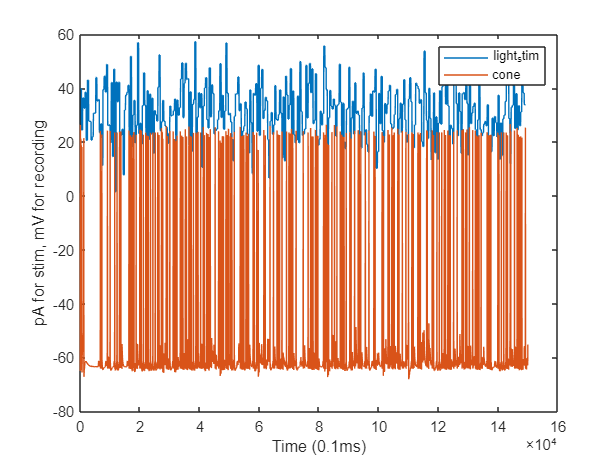

xlabel("Time (0.1ms)")
ylabel("pA for stim, mV for recording")
hold off



% plot(stim_wav)
% hold on
% plot(a2)
% plot(horizontal)
% plot(rod)
% plot(rodbip)
% legend('Stim',"A2", "Horizontal", "rod", "rod bipolar")
% xlim([9000, 11000])
% xlabel("Time (0.1ms)")
% ylabel("pA for stim, mV for recording")
% hold off